clear

% Read img file
img = imread("../db/DB1/db1_06.jpg")

img = 475×362×3 uint8 array
img(:,:,1) =

   226   227   227   226   225   226   227   227   227   227   228   228   227   227   227   228   227   227   227   227   227   227   226   226   224   225   226   228   230   229   226   224   224   226   228   228   227   226   226   226   225   226   225   224   226   228   227   225   224   225   227   227   226   226   226   226   225   227   228   227   225   224   226   228   225   227   224   224   228   227   224   227   226   227   227   226   226   226   226   226   225   225   226   226   226   226   225   225   226   226   227   227   227   226   226   226   227   226   226   226   226   227   227   227   227   225   224   225   226   225   224   224   224   224   224   224   224   224   224   224   225   225   224   224   224   224   225   225   222   224   226   226   224   223   224   225   225   224   225   226   225   224   223   224   224   224   223   223   223   223   224   224   225   225   225   224   223   222   223   2

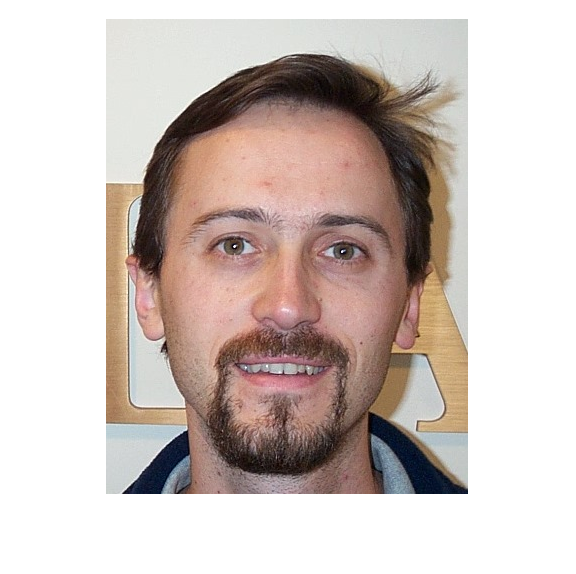

imshow(img)

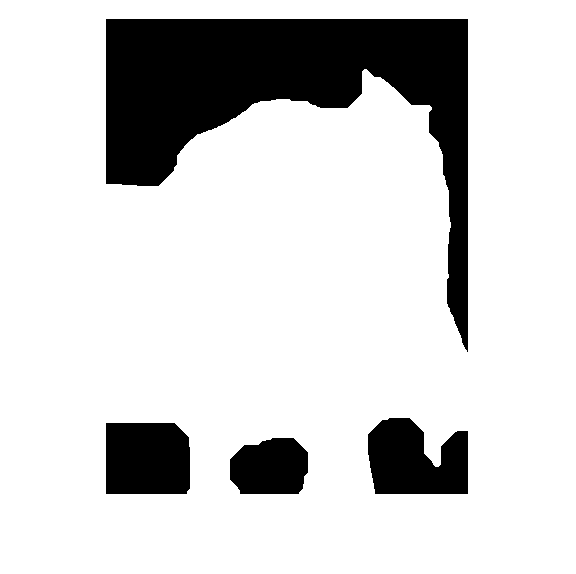

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)


%Find eyes and a mouth
eyes = eyemap(img_gw)

eyes =     0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0722    0.0722    0.0722    0.0722    0.0725    0.0725    0.0732    0.0732    0.0732    0.0727    0.0727    0.0727    0.0727    0.0727    0.0727    0.0726    0.0726    0.0731    0.0734    0.0734    0.0734    0.0734    0.0734    0.0734    0.0734    0.0734    0.0734    0.0734    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0727    0.0727
    0.0725    0.0725    0.0720    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0725    0.0722    0.0722    0.0725    0.0729    0.0732    0.0732    0.0732    0.0732    0.0727    0.0727    0.0727    0.0727    0.0727    0.0731    0.0731    0.0731    0.0734    0.0734    0.0734    0.0734    0.0729    0.0729    0.0734    0.0734    0.0734    0.0734    0.0734    0.0734    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731  

eye_mask = eyemask((eyes),face_mask)

eye_mask = 475×362 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

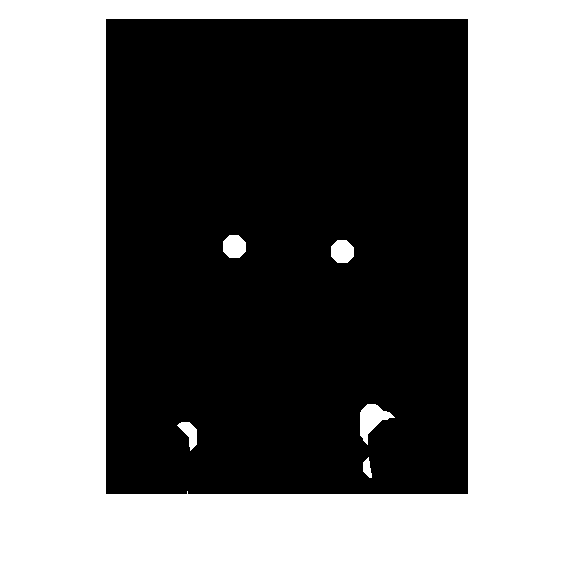



imshow(eye_mask);


mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask)

x = 176.7665

y = 362.7399

[indexX,indexY] = eye_index(eye_mask)

indexX =   128.8721  236.8721  261.8689


indexY =   228.1279  233.1279  449.6885



% eye_centers = cat(length(indexX),x,y);
%----------------------------------------%
% Calculate the center of the mouth (you might need to adjust this based on your specific case)
mouth_center = [x, y]; % replace with actual coordinates

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, indexY(:)];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));

% Find the indices of the two eyes with the closest distance to the mouth
%[~, sorted_indices] = sort(distances)
%closest_eye_indices = sorted_indices(1:2)
%closest_eyes = [indexX(closest_eye_indices), indexY(closest_eye_indices)]

% Beräkna avståndet mellan varje öga och ansiktets mitt
face_mid = [size(img, 2) / 2, size(img, 1) / 2]; % Mitt av ansiktet
eye_distances_to_mid = sqrt((indexX - face_mid(1)).^2 + (indexY - face_mid(2)).^2);

% Sortera ögonen baserat på avståndet till ansiktets mitt
[sorted_mid_distances, sorted_mid_indices] = sort(eye_distances_to_mid)

sorted_mid_distances =    52.9637   56.0430  227.0765


sorted_mid_indices =      1     2     3



% Välj de två ögonen som är närmast ansiktets mitt
closest_mid_eye_indices = sorted_mid_indices(1:2)

closest_mid_eye_indices =      1     2


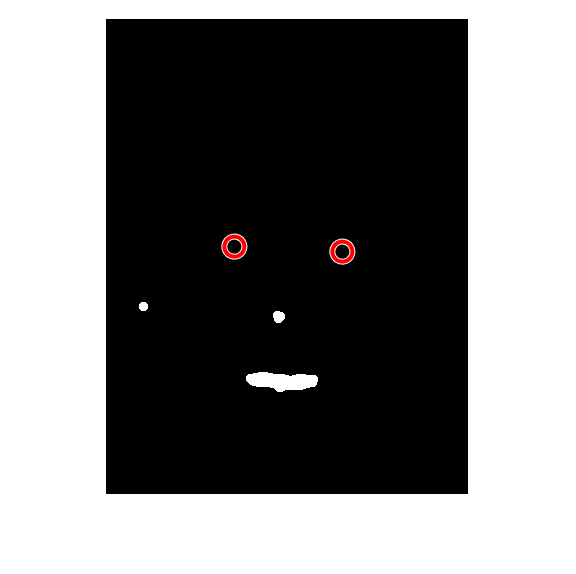

closest_mid_eyes = [indexX(closest_mid_eye_indices), indexY(closest_mid_eye_indices)];

%test

% Visualization
viscircles([closest_mid_eyes(1), closest_mid_eyes(3)], 10);
viscircles([closest_mid_eyes(2), closest_mid_eyes(4)], 10);

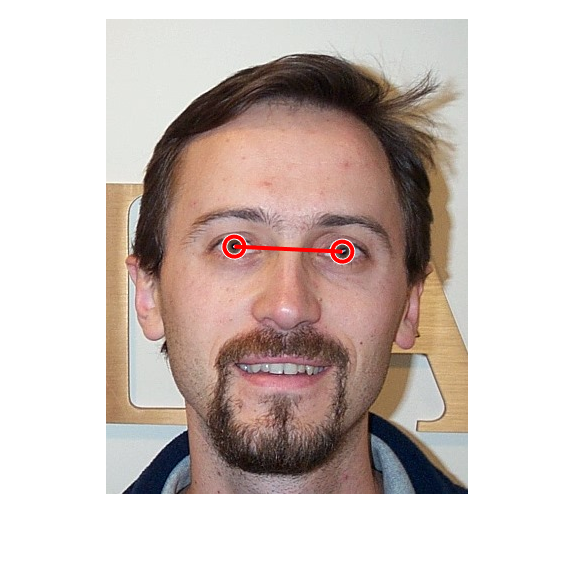


eye1 = [closest_mid_eyes(1), closest_mid_eyes(3)];
eye2 = [closest_mid_eyes(2), closest_mid_eyes(4)];


figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')

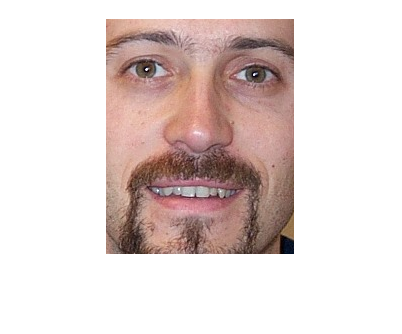


% Definiera antal pixlar från munnen neråt, ögonen uppåt, samt ögonen utåt
pixels_down_from_eyes = 180; % Antal pixlar från munnen neråt
pixels_up_from_eyes = 50;    % Antal pixlar från ögonen uppåt
pixels_sideways_from_eyes = 40; % Antal pixlar från ögonen utåt

% Beräkna koordinaterna för den nya rektangeln som inkluderar ansiktet
xmin = min([eye1(1), eye2(1)]) - pixels_sideways_from_eyes;
ymin = min([eye1(2), eye2(2)]) - pixels_up_from_eyes;
width = max([eye1(1), eye2(1)]) - xmin + pixels_sideways_from_eyes;
height = max([mouth(2), eye1(2), eye2(2)]) - ymin + pixels_down_from_eyes;

% Säkerställ att det inte går utanför bildens gränser
xmin = max(1, xmin);
ymin = max(1, ymin);
width = min(size(img, 2) - xmin + 1, width);
height = min(size(img, 1) - ymin + 1, height);

% Avrunda koordinaterna för att säkerställa att de är heltal
xmin = round(xmin);
ymin = round(ymin);
width = round(width);
height = round(height);

% Beskär bilden baserat på de beräknade koordinaterna
cropped_img = img(ymin:ymin+height-1, xmin:xmin+width-1, :);

% Visa den beskurna bilden
figure;
imshow(cropped_img)

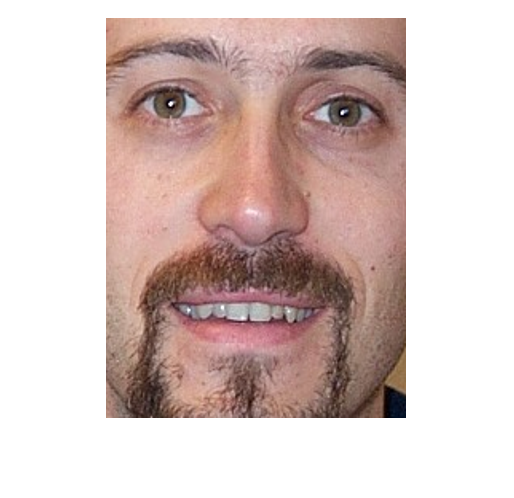


% Definiera önskad storlek för alla beskurna bilder
desired_height = 400;
desired_width = 300;

% Ändra storleken på den beskurna bilden till önskad storlek
resized_img = imresize(cropped_img, [desired_height, desired_width]);

% Visa den ändrade bilden till önskad storlek
figure;
imshow(resized_img);